# Week 3 Homework

* Robert Garrone*

*    Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

The four problem statements are given as:

Problem set III-1

Program 3.3.2 Three-Link Cylindrical Robot in Spong, using Eq. 3.1.4. 

Give theta 1 motion from 0 to 180 degrees, then d1 0 to 0.1 [m], d2 0 to 0.1 [m], d3 0 to 0.1 [m] (in sequence), and draw the path of the end-effector.

Problem set III-2

Consider the three-link articulated robot of Figure 3.18. Derive the forward kinematic equations using the DH convention as in Spong, Mark W.. Robot Modeling and Control (p. 97). Wiley. Kindle Edition. 

Program LiveScript code to plot the locations of o_i (including o_0) as as you enter motion parameters ( theta_i, or d_i)  in text boxes. 

Problem set III-3

- Watch the Denso's HSR robot again (Week 2). 

- Open the product specification [LINK.     (Links to an external site.)](https://www.densorobotics.com/products/4-axis/hsr-series/)Download a [catalog (Links to an external site.)](https://api.densorobotics.com/downloads/file/4). Consider 480 mm reach model with 100 mm z-stroke 

- Write DH parameters table **using the same set of link parameter use decided to use in Weak 2 assignment. **

- Rotate the first axis near the base 0 to 180 degrees clock wise (looking from above) from the initial Configuration Space with 1 degree interval. At the same time, rotate the second axis from the base 0 to 90 degrees clock wise (looking from above) from the initial Configuration Space with 0.5 degree interval.  At the same time, give z-axis a stroke ranging from 0 to 100 mm with 100/180 mm interval. Plot the tip of the third z-axis in Matlab.

- Congrats...now you are using Forward Kinematics in the text book in your real life applications! 

Problem set III-4

- Use the Robotic Systems Toolbox in Matlab to calculate the forward kinematics of the Denso's HSR robot.

- You can use the example of the Puma560 robot available in the toolboox:

- "Build Manipulator Robot Using Denavit-Hartenberg Parameters" 

- [https://www.mathworks.com/help/releases/R2018a/robotics/ref/robotics.rigidbodytree-class.html (Links to an external site.)](https://www.mathworks.com/help/releases/R2018a/robotics/ref/robotics.rigidbodytree-class.html)

- Using the function "getTransform" save and print the end-effector trajectory with the following joint input: 

- First joint: −pi/4·sin(2pi∗t)

- Second joint: pi/2·sin(4pi∗t)

- Other joints: zero

- Congrats..you are now using special programming toolkit for Robotics

### Approach:

Each of these stated problems requires its own individual approach. The approaches are summarized in the below subsections.

#### Problem Statement III-1:

The approach taken is to use the given DH parameter table and associated parameters in section 3.3.2 of Spong et al. to create the transformation matricies for each link. The transformation matricies for each link are then concatenated to create a composite homogeneous transformation that descibes the position of the end-effector relative to the base. The path of the end effector is then drawn by iterating though values defined for the joint variables in `linspace` arrays.

#### Problem Statement III-2:

Problem 3-5 in Spong et al. wants the reader to consider Figure 3.16, which consists of an articulatd robot with 3 links and derive the forward kinematic equations using the DH convention. 

The approact taken is to diagrammatically determine the DH parameters for the robot by completing a DH table for each link. With the complete table, the individual transformation matricies for each link can be found and concatenated to create a composite homogeneous transformation matricies that describe the position of each link's joint's coordinate frame with respect to the base frame. These coordinate frames can than be plotted and their positions made to change by varying the values of joint parameters with user input, which in this case will be via a slide control.  

#### Problem Statement III-3: 

Using the Denso Robot parameters used in last week's homework assignment, A simplified model of the robot will be created using DH convention. From this, a DH table can be filled out and homogeneous matricies that define the relationship between the frames can be generated and concatenated. Finally, the model is made to step through the described rotations and translations and the position of the tip of the end effector of the robot is plotted for each step. 

#### Problem Statement III-4: 

Using the Denso Robot parameters used in last week's homework assignment and the simplified model and DH table of the robot using DH convention, the Denso robot can be modeled using the MATLAB Roboitcs Toolkit. A robot object, `denso `is instantiated and bodies and their associated joints are added to the model based on the DH table. Finally, the joint positions are defined using the given equations for joint 1 and joint 2 and the model is iterated through positions. The positon coordinates for the end effector of the Denso robot are saved in arrays, and the resulting path of movement as descibed by the given equations for joint 1 and joint 2 is plotted. 

## Materials and Methods:

### General Methodology:

Denavit-Hartenberg (DH) convention is a widely-accepted convention for performing kinematic  analysis. While there are many ways to represent the relationships of an *n*-link robot, the DH convention provides a universal language for engineers to communicate these relationships. 

In DH convention, each homogeneous transformation $A_i$ is represented as a product of four basic transformations. 

- A rotation about z by $\theta$

- A translation in z by $d$

- A translation in x by $a$

- A rotation about x by $\alpha$

Spong et al. demonstrates this mathematically in equation 3.10

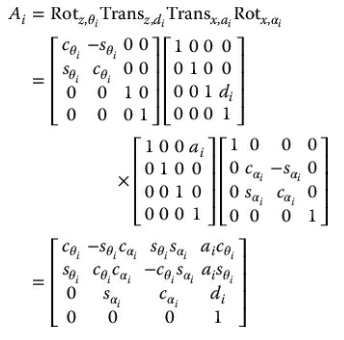

With the i subscript on each of these parameters to denote link i and join i. The four parameters $a_i ,\alpha_i ,d_i \;\mathrm{and}\;\theta_i$ are named link length, link twist, link offset and joint angle, respectively. These names are derived from how they each descibe the transformation from one coordinate frame to another.  It is to be noted that $A_i$ is described by a single variable, either $d_i \;\mathrm{or}\;\theta_i$ depending upon whether the joint is prismatic (linear) or revolute. The remaining 3 variables are to be held constant in a given matrix.

In order for the transformation to be able to represent any arbitrary homogeneous transformation with only 4 variables, the following two additional conventions must be observed:

- The axis $x_i$ is perpendicular to axis $z_{i-1}$

- The axis $x_i$ intersects the axis $z_{i-1}$

With these two constraints in mind, we can plainly state the physical interpretation or the "meaning" of each of the four joint variables:

- 
$$\theta_i \;\mathrm{is}\;\mathrm{the}\;\mathrm{rotation}\;\mathrm{about}\;\mathrm{axis}\;z_{i-1}$$


- 
$$\alpha_i \;\mathrm{is}\;\mathrm{the}\;\mathrm{angle}\;\mathrm{about}\;x_n \;\mathrm{between}\;\mathrm{axis}\;z_{i-1} \;\mathrm{and}\;z_n$$


- 
$$d_i \;\mathrm{is}\;\mathrm{the}\;\mathrm{displacment}\;\mathrm{along}\;\mathrm{axis}\;z_{i-1} \;\mathrm{between}\;\mathrm{the}\;\mathrm{origins}\;\mathrm{of}\;\;o_{n-1} \;\mathrm{and}\;o_n$$


- 
$$a_i \;\mathrm{is}\;\mathrm{the}\;\mathrm{displacment}\;\mathrm{along}\;\mathrm{axis}\;x_n \;\mathrm{between}\;z_{i-1} \;\mathrm{and}\;z_n$$


Applying these conventions to the joints and links of a robot involve the following steps as described in Spong et al.:

- Locate and label the joint axes from $z_0 \;\mathrm{through}\;z_{n-1}$

- Establish a convenient base frame. The $x_0 \;\mathrm{and}\;y_0$ axes are chosen to from a right handed frame

- For frame 1 through frame *n*-1, locate the origin  where the common normal to $z_i \;{\mathrm{and}\;z}_{i-1} \;$intersects $z_i$. If $z_i$ intersects $z_{n-1}$  locate the frame origin at this intersection. If $z_i \;\mathrm{and}\;z_{i-1}$ are parallel, locate the frame origin in any convenient position along $z_i$.

- Establish $x_i$ along the common normal between $z_{i-1} \;\mathrm{and}\;z_i$ through the frame origin , or in the direction normal to the $z_{i-1}$/$z_i$ plane if $z_{i-1}$ and $z_i$ intersect.

- Establish the $y_i \;$axis in such as way as to complete a right-handed frame

- Establish the end-effector coordinate frame . Assuming the nth joint is revolute, set $z_n =a$ parallel to $z_{n-1}$. Establish the origin conveniently along $z_n$, preferably at the center of the gripper or at the tip of any tool that the manipulator may be carrying. Set $y_n =s$ in the direction of the gripper closure and set $x_n =n$ as s × a. If the tool is not a simple gripper set $x_n$ and $y_n$ conveniently to form a right-handed frame.

- Create the table of DH parameters $a_i ,\alpha_i ,d_i ,\theta_i$. 

- Substitute these parameters into the homogeneous transform matrix $A_i$.

- Form a composite transform $T_n^0 =A_1 \ldotp \ldotp \ldotp A_n$ to get the end-effector position expressed in terms of base coordinates. 

A DH parameter relates the links to their respective parameters. It takes the form:

where **Link** is a column of numbered links and ${\mathit{\mathbf{a}}}_{\mathit{\mathbf{i}}} ,\alpha_{\mathit{\mathbf{i}}} ,{\mathit{\mathbf{d}}}_{\mathit{\mathbf{i}}} ,\theta_{\mathit{\mathbf{i}}}$ are columns of the numbered respective parameters. 

With this background, it is possible to compute the forward kinematic relationships for the manipulators given in Problem Statements III-1 to III-4. 

### Problem Statement III-1:

The three-link cynlindrical manipulator in section 3.3.2 of Spong et al. is shown as:

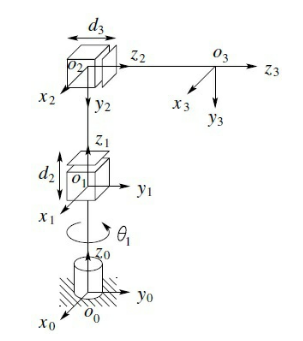

From Spong, the DH table for the cylindrical robot is given as:


$$\matrix{
\text{Link} & {a_i} & \alpha_i & d_i & \theta_i
\cr
1 & 0 & 0	& d_1 & \theta_1
\cr
2 & 0 & -90 & d_2 & 0
\cr
3 & 0 & 0	& d_3 & 0
\cr
}$$


Which, following the procedure outlined in the General Methodology section, generates the homogeneous matricies $A_1 {,\;A}_2 ,{\;A}_3$ and composite matrix $T_3^0$:$\;$ 

syms theta_1 theta_2 d_1 d_2 d_3 

A_1cyl = [cos(theta_1) -sin(theta_1) 0 0; sin(theta_1) cos(theta_1) 0 0; 0 0 1 d_1; 0 0 0 1]

$$A\_1cyl = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_2cyl = [1 0 0 0; 0 0 1 0; 0 -1 0 d_2; 0 0 0 1]

$$A\_2cyl = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_3cyl = [1 0 0 0; 0 1 0 0; 0 0 1 d_3; 0 0 0 1]

$$A\_3cyl = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T03cyl = A_1cyl * A_2cyl * A_3cyl

$$T03cyl = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & -d_{3}\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & d_{3}\,\cos\left(\theta_{1}\right)\\ 0 & -1 & 0 & d_{1}+d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

For Problem Statement 1, the DH parameter table is already defined. The matricies  `A_1cyl`, `A_2cyl` and `A_3cyl` are defined using equation 3.10 from Spong et al with the appropriate parameters subsituted in for the cylindrical robot. The resulting composite matrix T03cyl describes the position of the robot end-effector in terms of the base frame. 

### Problem Statement II-2:

 The three-link articulated robot is given in Problem 3-5 as shown:

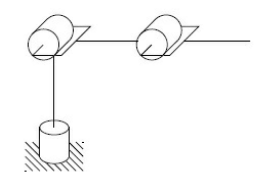

Applying the conventions of DH parameters on the robot yields the following diagram and parameter table:

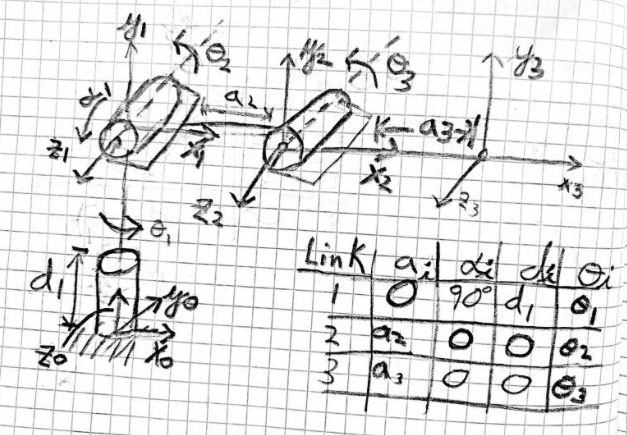

In general, $a_i ,\alpha_i ,d_i ,\theta_i$ are defined for each axis. $\theta_i$ is assigned to be a counterclockwise rotation about axis $z_{i-1}$. $\alpha_i$ is shown as a change in angle between $z_{i-1} \;\mathrm{and}\;z_i$ about $x_n$. $d_i$ is the displacement in the $z_{n-1}$direction and $a_i$ is the displacement along the $x_i$direction. The z axis for each coordinate frame is conveniently placed in the direction of the joint axis and the x axis for each frame is placed perpendicular to both the z axis of its own coordinate frame and perpendicular to the one preceeding it.

Again, the general form of a transformation matrix is:


$$A_i \;=\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i } c_{\alpha_i }  & s_{\theta_i } s_{\alpha_i }  & a_i c_{\theta_i } \\
s_{\theta_i }  & c_{\theta_i } c_{\alpha_i }  & -c_{\theta_i } s_{\alpha_i }  & a_i s_{\theta_i } \\
0 & s_{\alpha_i }  & c_{\alpha_i }  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Using MATLAB to symbolically compute, the transformations $A_1 \;\mathrm{through}\;A_3$ are:

syms a_2 a_3 d_1 c_1 c_2 c_3 s_1 s_2 s_3

A_1art = [c_1 0 s_1 0; s_1 0 -c_1 0; 0 1 0 d_1; 0 0 0 1]

$$A\_1art = \left(\begin{array}{cccc} c_{1} & 0 & s_{1} & 0\\ s_{1} & 0 & -c_{1} & 0\\ 0 & 1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_2art = [c_2 -s_2 0 a_2*c_2; s_2 c_2 0 a_2*s_2; 0 0 1 0; 0 0 0 1]

$$A\_2art = \left(\begin{array}{cccc} c_{2} & -s_{2} & 0 & a_{2}\,c_{2}\\ s_{2} & c_{2} & 0 & a_{2}\,s_{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_3art = [c_3 -s_3 0 a_3*c_3; s_3 c_3 0 a_3*s_3; 0 0 1 0; 0 0 0 1]

$$A\_3art = \left(\begin{array}{cccc} c_{3} & -s_{3} & 0 & a_{3}\,c_{3}\\ s_{3} & c_{3} & 0 & a_{3}\,s_{3}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T03art = A_1art * A_2art * A_3art

$$T03art = \left(\begin{array}{cccc} c_{1}\,c_{2}\,c_{3}-c_{1}\,s_{2}\,s_{3} & -c_{1}\,c_{2}\,s_{3}-c_{1}\,c_{3}\,s_{2} & s_{1} & a_{2}\,c_{1}\,c_{2}-a_{3}\,c_{1}\,s_{2}\,s_{3}+a_{3}\,c_{1}\,c_{2}\,c_{3}\\ c_{2}\,c_{3}\,s_{1}-s_{1}\,s_{2}\,s_{3} & -c_{2}\,s_{1}\,s_{3}-c_{3}\,s_{1}\,s_{2} & -c_{1} & a_{2}\,c_{2}\,s_{1}-a_{3}\,s_{1}\,s_{2}\,s_{3}+a_{3}\,c_{2}\,c_{3}\,s_{1}\\ c_{2}\,s_{3}+c_{3}\,s_{2} & c_{2}\,c_{3}-s_{2}\,s_{3} & 0 & d_{1}+a_{2}\,s_{2}+a_{3}\,c_{2}\,s_{3}+a_{3}\,c_{3}\,s_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Note that $c_i \;\mathrm{and}\;s_i$ are shorthand for $\mathrm{cos}\left(\theta_i \right)\;\mathrm{and}\;\mathrm{sin}\left(\theta_i \right)$.

### Problem Statement III-3:

Using the background for DH parameters provided in the General Methodology section, it is possible to describe the Denso Robot from Week 2 using DH convention. 

The catalog provided gives these dimensional specifications for the robot. 

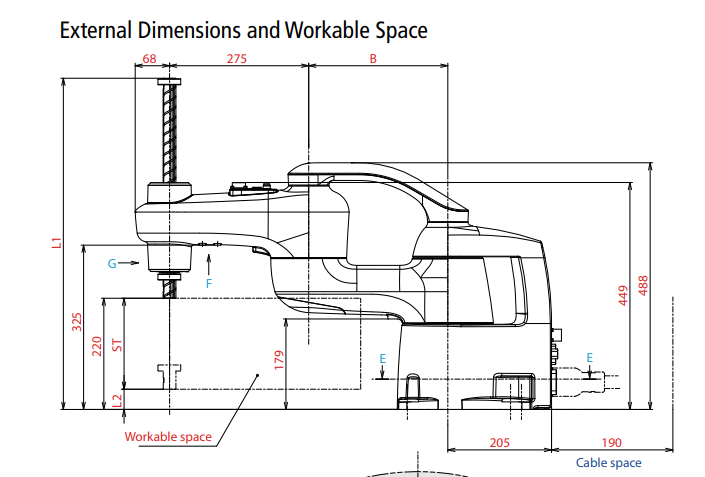

For the 480mm maximum reach robot, B in the figure is given as 205mm.

A simplified drawing of this robot was created using DH conventions to describe frame relationship and joint variables. Spong et al. provides a derivation of the DH parameters of the SCARA robot that this derivation was checked against. The same logical steps for labeling joint axes apply from Problem Statement III-2:

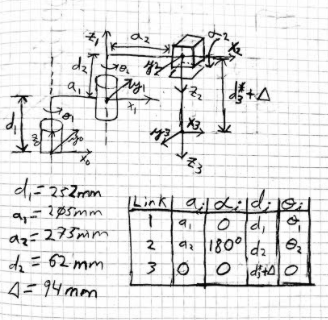

The simplified model above makes a few assumptions about the location of the coordinate frames based on the dimensions given for the Deno robot, chiefly:

- The center of the first joint from the base is $\frac{179+325}{2}=252\textrm{mm}$ in z from the base

- The center of the second joint from the base is $\frac{449+179}{2}=314\textrm{mm}$ in z from the base

- The tip of the end effector is 314-94mm= 220mm in z from the base

As shown in the drawing, the DH paramter table is 


$$\matrix{
\text{Link} & {a_i} & \alpha_i & d_i & \theta_i
\cr
1 & a_1 & 0 & d_1 & \theta_1
\cr
2 & a_2 & \pi & d_2 & \theta_2
\cr
3 & 0 & 0 & d^*_3 + \Delta & 0
\cr
}$$


with $d_3^*$ representing the prismatic joint variable and $\Delta$ repesenting a constant link offset between the prismatic joint and the end effector.

The constants $a_1 ,a_2 ,\;d_1 ,d_2 ,\textrm{and}\;\Delta \;$are defined as 

- 
$$a_1 =205\textrm{mm}$$


- 
$$a_2 =275\textrm{mm}$$


- 
$$d_1 =252\textrm{mm}$$


- 
$$d_2 =62\textrm{mm}$$


- 
$$\Delta =94\textrm{mm}$$


Given the table, we can realize each row as a homogeneous transform in this form:


$$A_i \;=\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i } c_{\alpha_i }  & s_{\theta_i } s_{\alpha_i }  & a_i c_{\theta_i } \\
s_{\theta_i }  & c_{\theta_i } c_{\alpha_i }  & -c_{\theta_i } s_{\alpha_i }  & a_i s_{\theta_i } \\
0 & s_{\alpha_i }  & c_{\alpha_i }  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Using MATLAB, we generate each A transform and concatenate them to describe the system as a single transform $T_3^0$

syms c_1 s_1 c_2 s_2 c_3 s_3 d_3

A_1denso = [c_1 -s_1 0 205*c_1; s_1 c_1 0 205*s_1; 0 0 1 252; 0 0 0 1]

$$A\_1denso = \left(\begin{array}{cccc} c_{1} & -s_{1} & 0 & 205\,c_{1}\\ s_{1} & c_{1} & 0 & 205\,s_{1}\\ 0 & 0 & 1 & 252\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_2denso = [c_2 s_2 0 275*c_2; s_2 -c_2 0 275*s_2; 0 0 -1 62; 0 0 0 1]

$$A\_2denso = \left(\begin{array}{cccc} c_{2} & s_{2} & 0 & 275\,c_{2}\\ s_{2} & -c_{2} & 0 & 275\,s_{2}\\ 0 & 0 & -1 & 62\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A_3denso = [1 0 0 0; 0 1 0 0; 0 0 1 d_3+94; 0 0 0 1]

$$A\_3denso = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}+94\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_03denso = A_1denso*A_2denso*A_3denso

$$T\_03denso = \left(\begin{array}{cccc} c_{1}\,c_{2}-s_{1}\,s_{2} & c_{1}\,s_{2}+c_{2}\,s_{1} & 0 & 205\,c_{1}+275\,c_{1}\,c_{2}-275\,s_{1}\,s_{2}\\ c_{1}\,s_{2}+c_{2}\,s_{1} & s_{1}\,s_{2}-c_{1}\,c_{2} & 0 & 205\,s_{1}+275\,c_{1}\,s_{2}+275\,c_{2}\,s_{1}\\ 0 & 0 & -1 & 220-d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Problem Statement III-4:

Robot models can be implemented using the Robotics Toolbox that is available as an Add-On in MATLAB. The toolbox provides useful tools for modelling the forward kinematics of robot models. Problem Statement III-4 asks us to model the Denso 3-axis SCARA robot using this toolbox.

The first step is to create a robot rigidBodyTree object and specify the robot DH parameters to be used. 

%Define DH parameters in a matrix that realizes the DH table
dhparams = [205 0 252 0;275	pi 62 0;0 0 94 0]

dhparams =   205.0000         0  252.0000         0
  275.0000    3.1416   62.0000         0
         0         0   94.0000         0



%instantiate robot object
denso = rigidBodyTree;

The DH table is defined without joint variables. That is, the variables can all be considered initialized to 0. Only constants are passed to the table. The joint variability can be expressed by explicitly changing the position of the joint, which we will do later on. 

Next, we may define the body and joint objects for the SCARA robot. 

%define bodies and joints
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');

Here we define the links as `body1, body2, body 3` and the joints as `jnt1, jnt2, jnt3.` `jnt1` and `jnt2` are specified as 'revolute' while `jnt3` is specified as 'prismatic', which is congruent with the Denso SCARA robot.

Next, we associate the rows of the DH parameter table with the joints themselves:

%set the transform for each joint according to the DH paramter table
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');

Then we may associate the joints with their respective bodies:

%associate joints with links aka bodies
body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;

With the bodies and joints associated, we can add the bodies to the `denso` robot object:

%add bodies to robot and connect the bodies together
addBody(denso,body1,'base');
addBody(denso,body2,'body1');
addBody(denso,body3,'body2');

Each call to `addBody` takes the `denso` robot object, a `body` object and an association to the previous link. Here, for example, `body1`'s previous link is the base frame. 

With the robot linkage and joints now associated with each other, the robot can be viewed graphically and parametrically:

%check the new denso robot model
showdetails(denso);

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   
--------------------


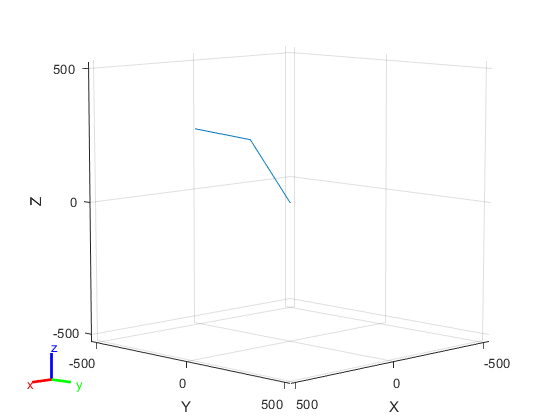

ans =   Axes (Primary) with properties:

             XLim: [-528 528]
             YLim: [-528 528]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(denso);

## Results:    

### Problem Statement III-1:

In the previous section, we obtained the transformation matricies for the cylindrical robot after being given the DH convention labeled diagram and associated DH parameter table. We can now step the model's end effector through a path. 

The cylindrical manipulator can be made to step through positions by defining path points for each joint variable using `linspace` arrays. Constant$\;d_1$is also defined:

theta1pts = linspace(0,180,180); %theta defined here in degrees, will convert to rads
d2pts = linspace(0,0.1,180);
d3pts = linspace(0,0.1,180);
d1val = 0.1; 

With the joint variable values now defined as linearly spaced steps, it is possible to calculate the position of the end-effector for each step:

%pre-allocate the array spaces in memory to speed up calc time. 
%merely a 1x180 array of all 0's
x_effector = zeros(1,180); 
y_effector= zeros(1,180);
z_effector = zeros(1,180);

%Homogeneous representation of point 0,0,0 in coord. frame 3
effector_start_pt = [0;0;0;1]; 

%step through all 180 degrees of the end effector tip
for i = 1:180
    %A's are defined with numerical values for joint parameters   
    A_1cyl = [cos(deg2rad(theta1pts(1,i))) -sin(deg2rad(theta1pts(1,i))) 0 0; sin(deg2rad(theta1pts(1,i))) cos(deg2rad(theta1pts(1,i))) 0 0; 0 0 1 d1val; 0 0 0 1];
    A_2cyl = [1 0 0 0; 0 0 1 0; 0 -1 0 d2pts(1,i); 0 0 0 1];
    A_3cyl = [1 0 0 0; 0 1 0 0; 0 0 1 d3pts(1,i); 0 0 0 1];
    
    %create composite H
    T_03cyl = A_1cyl * A_2cyl * A_3cyl; 
    
    %apply transformation to effector start pt
    transformed_pt = T_03cyl*effector_start_pt;
    
    %add x,y,z coordinates w.r.t. base frame to x,y,z coordinate-holding arrays
    x_effector(1,i) = transformed_pt(1,1);
    y_effector(1,i) = transformed_pt(2,1);
    z_effector(1,i) = transformed_pt(3,1);
    
end

Above, we define the $A_i$ matricies in the same way as they were defined in the Materials and Methods sections, except with the symbolic joint parameters subsituted for given or variable joint parameters. 

For the variable parameters, we iterate through values in the `linspace` arrays defined for each joint variable, create a concatenated composite matrix of the A transforms and apply it to a dummy variable that represents a point in the origin at coordinate frame 3 to express the position of that point with respect to the base frame. We then, for each iteration, collect the x,y,z coordinates in respective arrays for plotting. 

 Plotting the end effector coordinate arrays yields:

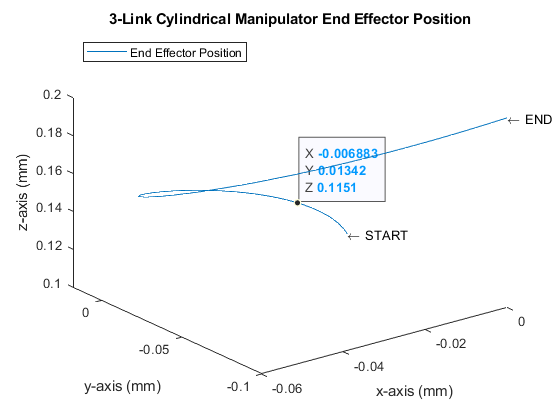

plot3(x_effector,y_effector,z_effector);
title('3-Link Cylindrical Manipulator End Effector Position')
text(x_effector(1,1),y_effector(1,1),z_effector(1,1),"\leftarrow START");
text(x_effector(1,180),y_effector(1,180),z_effector(1,180),"\leftarrow END");
xlabel('x-axis (mm)')
ylabel('y-axis (mm)')
zlabel('z-axis (mm)')
legend('End Effector Position', 'Location',"northwest")

### Problem Statement III-2:

In the previous section we obtained a DH representation for the articulated robot. We created a DH parameter table for the  joint parameters of each link and from this defined homogeneous equations relating the links. We can now use these relationships to depict the locations of the joint axes and how they vary as the joint variables change.

We can make use of the controls features in MATLAB live to create interactive sliding bars to vary the input joint parameters and plot the locations of each link's coordinate frame. 

theta_1 =0;
theta_2 =0;
theta_3 =0;
d_1 = 1;
a_2 = 1;
a_3 = 1;

Here, the constants `d_1, a_2 `and `a_3` are defined as 1 for convenience. The sliding scales for the 3 joint angles range from -180 degrees to 180 degrees and are initialized to 0. 

Next, we define the transformation matricies $A_{1\;} ,A_2 ,\mathrm{and}\;A_3$ as well as dummy points for each coordinate frame origin:

%A transforms for each link
A_1art = [cos(deg2rad(theta_1)) 0 sin(deg2rad(theta_1)) 0; sin(deg2rad(theta_1)) 0 -cos(deg2rad(theta_1)) 0; 0 1 0 d_1; 0 0 0 1];
A_2art = [cos(deg2rad(theta_2)) -sin(deg2rad(theta_2)) 0 a_2*cos(deg2rad(theta_2)); sin(deg2rad(theta_2)) cos(deg2rad(theta_2)) 0 a_2*sin(deg2rad(theta_2)); 0 0 1 0; 0 0 0 1];
A_3art = [cos(deg2rad(theta_3)) -sin(deg2rad(theta_3)) 0 a_3*cos(deg2rad(theta_3)); sin(deg2rad(theta_3)) cos(deg2rad(theta_3)) 0 a_3*sin(deg2rad(theta_3)); 0 0 1 0; 0 0 0 1];

%Dummy points for each frame origin.
%To be multiplied by the transformations above
pt0 = [0;0;0;1];
pt1 = [0;0;0;1];
pt2 = [0;0;0;1];
pt3 = [0;0;0;1];

These equations are identical to those defined in the Materials and Methods section but have the sliding scale variables substituted in for the joint angle symbolic variables.

Next, we can define the origins of each coordinate frame by applying the proper transforms to the dummy origin points to obtain the locations of the coordinate frames and collect the coordinates in x, y and z arrays.

%define the origins of each coordinate frame
o0x0y0z0 = pt0

o0x0y0z0 =      0
     0
     0
     1


o1x1y1z1 = A_1art*pt1

o1x1y1z1 =      0
     0
     1
     1


o2x2y2z2 = A_1art*A_2art*pt2

o2x2y2z2 =      1
     0
     1
     1


o3x3y3z3 = A_1art*A_2art*A_3art*pt3

o3x3y3z3 =      2
     0
     1
     1



%collect the coordinate points
x_coords = [o0x0y0z0(1,1) o1x1y1z1(1,1) o2x2y2z2(1,1) o3x3y3z3(1,1)];
y_coords = [o0x0y0z0(2,1) o1x1y1z1(2,1) o2x2y2z2(2,1) o3x3y3z3(2,1)];
z_coords = [o0x0y0z0(3,1) o1x1y1z1(3,1) o2x2y2z2(3,1) o3x3y3z3(3,1)];

Finally we plot the coordinate frames on a single figure:

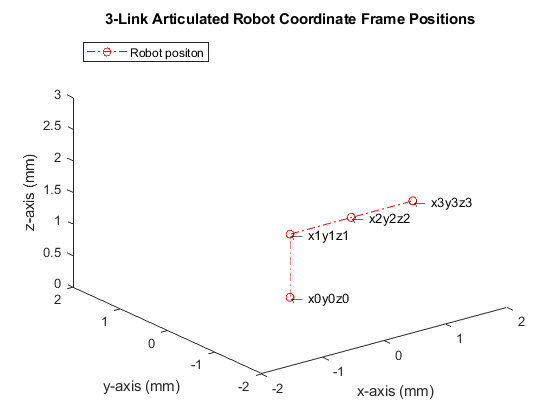

figure;
plot3(x_coords,y_coords,z_coords,'-.or');
text(x_coords(1,1),y_coords(1,1),z_coords(1,1),"\leftarrow x0y0z0");
text(x_coords(1,2),y_coords(1,2),z_coords(1,2),"\leftarrow x1y1z1");
text(x_coords(1,3),y_coords(1,3),z_coords(1,3),"\leftarrow x2y2z2");
text(x_coords(1,4),y_coords(1,4),z_coords(1,4),"\leftarrow x3y3z3");
axis([-2 2 -2 2 0 3])
title('3-Link Articulated Robot Coordinate Frame Positions')
xlabel('x-axis (mm)')
ylabel('y-axis (mm)')
zlabel('z-axis (mm)')
legend('Robot positon', 'Location',"northwest")

Each origin can be made to vary in position by adjusting the sliding scales created above. 

### Problem Statement III-3:

In the Materials and Methods section, we derived a DH representation of the Denso 3-axis robot system. With the homogeneous transform matrix defined, we can now plot a path of motion. 

Using `linspace` it is possible to step through different values for each joint variable so as to create a path with successive points when the matrix is made to transform a point at the origin of the end effector coordinate frame.

theta1densopts = linspace(0,180,180); %theta defined here in degrees, will convert to rads
theta2densopts = linspace(0,-90,180); %again defined in degrees
d3densopts = linspace(0,100,180);

With the steps defined for each joint variable, we can now iterate through each step and point the resulting plots. 


%pre-allocate the array spaces in memory to speed up calc time. 
%merely a 1x180 array of all 0's
x_effector = zeros(1,180); 
y_effector= zeros(1,180);
z_effector = zeros(1,180);

%Homogeneous representation of point 0,0,0 in coord. frame 3
effector_start_pt = [0;0;0;1]; 

%step through all 180 degrees of the end effector tip
for i = 1:180
    %A's are defined with numerical values for joint parameters   
    A_1denso = [cos(deg2rad(theta1densopts(1,i))) -sin(deg2rad(theta1densopts(1,i))) 0 205*cos(deg2rad(theta1densopts(1,i))); sin(deg2rad(theta1densopts(1,i))) cos(deg2rad(theta1densopts(1,i))) 0 205*sin(deg2rad(theta1densopts(1,i))); 0 0 1 252; 0 0 0 1];
    A_2denso = [cos(deg2rad(theta2densopts(1,i))) sin(deg2rad(theta2densopts(1,i))) 0 275*cos(deg2rad(theta2densopts(1,i))); sin(deg2rad(theta2densopts(1,i))) -cos(deg2rad(theta2densopts(1,i))) 0 275*sin(deg2rad(theta2densopts(1,i))); 0 0 -1 62; 0 0 0 1];
    A_3denso = [1 0 0 0; 0 1 0 0;0 0 1 d3densopts(1,i)+94; 0 0 0 1];
    
    %create composite H
    T_03denso = A_1denso*A_2denso*A_3denso; 
    
    %apply transformation to effector start pt
    transformed_pt = T_03denso*effector_start_pt;
    
    %add x,y,z coordinates w.r.t. base frame to x,y,z coordinate-holding arrays
    x_effector(1,i) = transformed_pt(1,1);
    y_effector(1,i) = transformed_pt(2,1);
    z_effector(1,i) = transformed_pt(3,1);
    
end

Above, we used the equations gotten in the Materials and Methods section to define our $A_i$ matricies. We plugged in a linspace array value for each joint variable and created a composite matrix `T_03denso`. We then multiplied the composite matrix against a dummy origin point vector to obtain the transformed point in coordinate frame 3 with respect to the base frame. We then iterated through the values in the arrays and repeated this process, collected the x,y,z coordinates of the transformed point into x, y and z arrays.

Plotting the end effector coordinate arrays yields:

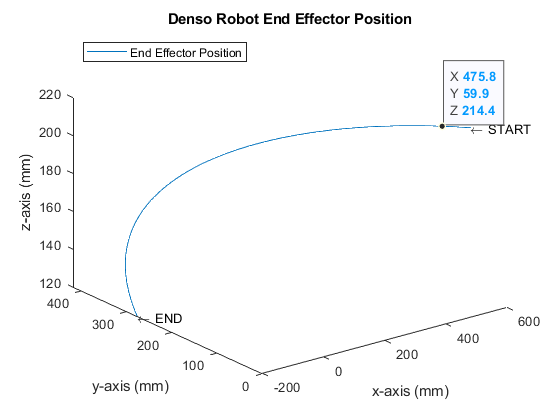

plot3(x_effector,y_effector,z_effector);
title('Denso Robot End Effector Position')
text(x_effector(1,1),y_effector(1,1),z_effector(1,1),"\leftarrow START");
text(x_effector(1,180),y_effector(1,180),z_effector(1,180),"\leftarrow END");
xlabel('x-axis (mm)')
ylabel('y-axis (mm)')
zlabel('z-axis (mm)')
legend('End Effector Position', 'Location',"northwest")

### Problem Statment III-4:

With the robot assembled as a relationship of connected links and joints as shown in the Materials and Methods section, we can now step through joint variable values given by the two equations in the Problem Statement

To do this, we first need to define a home configuration and a "dummy" origin column vector to represent the point at the origin of the end effector coordinate frame:

%define config and dummy origin coordinate
config = homeConfiguration(denso);
pt_denso = [0;0;0;1];

`The homeConfiguration()` function creates a structure to hold the joint position values. We assign this struct to `config. `We step through joint variables by modifing the joint positions in `config` in an iterative way by re-defining the `JointPosition` attribute of the `config` struct to the output of the joint 1 and joint 2 equations. After modifying the joint position value, the `getTransform()` function can be used to generate the composite transformation matrix that expresses points in frame 3 with respect to frame 0. 

To iterate for points to plot, we create a for loop over t that increments t, the variables in the functions that describe the movement of joints 1 and 2 of the robot. We then acquire the composite matrix `T03` as described above and apply it to the dummy origin column vector to yield the transformed point at the end effector in terms of the base coordinate frame. The x, y and z coordinates of this point are then saved in individual x, y and z arrays for plotting.    

%pre-allocate the array spaces in memory to speed up calc time. 
%merely a 1x10 array of all 0's
x_effector_denso = zeros(1,101); 
y_effector_denso= zeros(1,101);
z_effector_denso = zeros(1,101);

index = 1; %needed for x,y,z value arrays
for t = 0:.01:1
    config(1).JointPosition = (-pi/4*sin(2*pi*t));
    config(2).JointPosition = (pi/2*sin(4*pi*t));
    T03 = getTransform(denso,config,'body3');

    %apply transform to point at origin of frame 6
    end_effector_pt = T03*pt_denso;
    
    %add x,y,z coordinates w.r.t. base frame to x,y,z coordinate-holding arrays
    x_effector_denso(1,index) = end_effector_pt(1,1);
    y_effector_denso(1,index) = end_effector_pt(2,1);
    z_effector_denso(1,index) = end_effector_pt(3,1);
    index = index + 1;
end

Finally, we can plot the x, y and z coordinates of the transformed points for each step in position of the end effector:

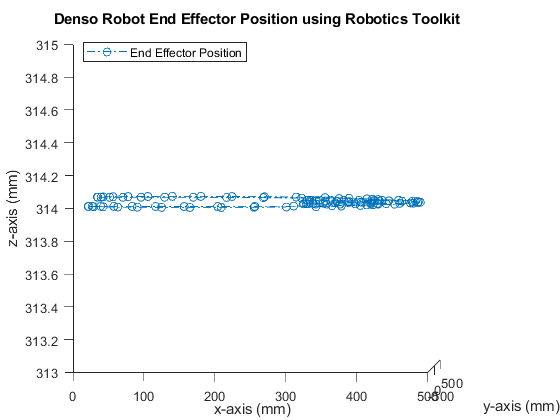

index =index-1; %decrement to match array size
plot3(x_effector_denso,y_effector_denso,z_effector_denso, '-.o');
title('Denso Robot End Effector Position using Robotics Toolkit')
xlabel('x-axis (mm)')
ylabel('y-axis (mm)')
zlabel('z-axis (mm)')
legend('End Effector Position', 'Location',"northwest")

Going further, we can assign the point values for the motion to a 3-column (x, y, z) matrix and print it:

%Create printout of x,y,z coordinates
%each column is x, y or z and each row is a point plotted
coord_denso_end_effector=zeros(101,3);
for j = 1:101
    coord_denso_end_effector(j,1) = x_effector_denso(1,j); %x column
    coord_denso_end_effector(j,2)= y_effector_denso(1,j); %y column
    coord_denso_end_effector(j,3) = z_effector_denso(1,j); %z column
end

coord_denso_end_effector %show coordinates as described

coord_denso_end_effector =   480.0000         0  314.0000
  476.7624   30.3256  314.0000
  467.3507   59.0707  314.0000
  452.6256   84.8485  314.0000
  433.8901  106.6194  314.0000
  412.7224  123.7773  314.0000
  390.7975  136.1542  314.0000
  369.7254  143.9526  314.0000
  350.9326  147.6247  314.0000
  335.5895  147.7255  314.0000


## Discussion:

### Problem Set III-1:

Given the DH convention model for the cylindrical manipulator robot and the DH parameter table, the transformation matricies $A_i$ and the composite matrix $T_3^0$ were successfully represented both symbolically and computationally. The position of the end effector was then varied by itering through values defined in `linspace` arrays and the position coordinates collected and plotted. 

The resulting path is satisfying given the instruction to rotate the joint angle from 0 to 180 degrees and to actuate the prismatic joints from 0 to 0.1m. The path is upward, counterclockwise and widens as it progresses from start to finish, just as it is described in the problem statement. 

### **Problem Set III-2:**

The articulated robot given in Figure 3-16 of Spong et al. was successfully labeled as per DH convention, its DH parameter table generated and its homogeneous transforms computed. From these computed transforms, we were able to relate the position of each joint axis to the base frame and plot the points of the origins of each coordinate frame from the coordinates obtained from the associated homogeneous transforms. 

The choice and ability to define the joint variables with a sliding controller from -180 to 180 degrees served as an apt illustration of how the joint axes vary in position as the joint variables vary in value. The exercise of varying the joint variable values and watching the plots change helped strenghen my understanding of how the joint variables relate to the position of not only the end effector but also the joints and links themselves. 

Choosing to define the limits for the slide scale as -180 to 180 was arbitrary but was motivated by the thinking that an actual joint would typically not rotate more than 180 degrees in any direction. Having a scale from 0 to 360 degrees, given this, seemed unrealistic. It is understood that most real-life joints will not have articulation as wide as -180 to 180 degrees but felt realistic enough. 

### Problem Set III-3:

The Denso HSR series robot was successfully represented,analyzed and modeled in MATLAB using DH parameters. To do this, the Denso HSR robot's specifications were identified in the Denso catalog provided and defined as they were previously in Week 2. From this, a model descibed by DH convention was created and a DH parameter table was established.

The assumptions made were regarding the location in base frame z of the joint axes and the offset distance from the prismatic joint to the end effector itself. In both joint axes cases, an average of 2 heights was taken whose result looked to at least approximate the joint centers. For the end effector, the offset from the prismatic joint to the end effector was assumed to be the difference between the z height of the second joint with respect to base frame and the end effector height given in the Denso catalog diagram. This assumed offset was 94mm and was included as a constant in the $d_3$ variable as $\Delta$. 

Using DH convention to represent the Denso SCARA robot, I obtained a very similar cure to what I obtained in the analysis performed on the Denso Robot in Week 2. The curve starts at (480, 0 ,220) and ends at (-205, 275, 120) . For reference, the curve from Week 2 started at at (0,480,220) in terms of the base frame and ended at (-275,-205,120). The fact that the positions are essentially the same with the exception of how they are expressed in terms of axis and sign gives me confidence in the DH convention as well as in the derivation of the path gotten in this Report. Furthmore the path is visually counterclockwise and downward, as expected. The end point is 100mm down from the start point and the absolute sum of the x and y values is 480, which suggests a circular rotation. 

### Problem Set III-4:

The Matlab Robotics Toolbox was successfully used to represent the 3-axis SCARA robot and plot the position of the end effector for the given x and y equations for joint motion.

Use of the robotics toolkit once the DH parameter table is obtained is relatively easy and conveient after an understanding of how to represent the robot links and joints is established. While not shown in this report, I first practiced using the example Puma560 robot parameters to get an intuitve understanding for how the robot is build up by defining and connecting individual bodies and associated joints. I initially struggled with how to represent joint variables and ultimately relied on the PUMA560 example to guide my DH parameter table initializion for the Denso Robot, choosing to set all joint variables to 0 and only keeping the constant parameters in the table. Searching online revealed that one is able to change the joint positions by creating modifying the `config` structure. Using this understanding, I was able to iterate variable `t `through values and modify the joint position with each iteration.

After collecting and plotting the points for the end effector, the graph is intuitively satisfying. The z position of the end effector is constant and ought to be considering that the end effector has not been actuated. The plot in x-y of the end effector is continuous and repetitive. This is expected as it is defined by sinusoidal functions.

Admittedly, the z-location of the height of the end effector does not meet my expectations. While 314mm is the z height of the prismatic joint, the end effector ought to be at 220mm, as there is an offset of 94 from the prismatic joint to the tip of the end effector. This is accounted for in the DH parameter table for the end effector link yet it does not seem to show up in the path of the end effector. Furthermore, it is clearly accounted for in the Results section of Problem Statement III-3. More investigation is needed into this discrepancy. 

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (pp. 35-74) (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- [MATLAB Robotics Toolbox Puma Robot Example](https://www.mathworks.com/help/releases/R2018a/robotics/ref/robotics.rigidbodytree-class.html)

- [Denso Robot Catalog (For HSR Specs)](https://dc-docs.dcatalog.com/Densocompany/Robotics/72c75621-8544-41b4-9afa-a7f60153efbd/DENSO_Robotics_Catalog_D2277470.pdf?v=16000223827980.19439691676377646)